# Implicit Deep Learning on the Forest Fire Dataset

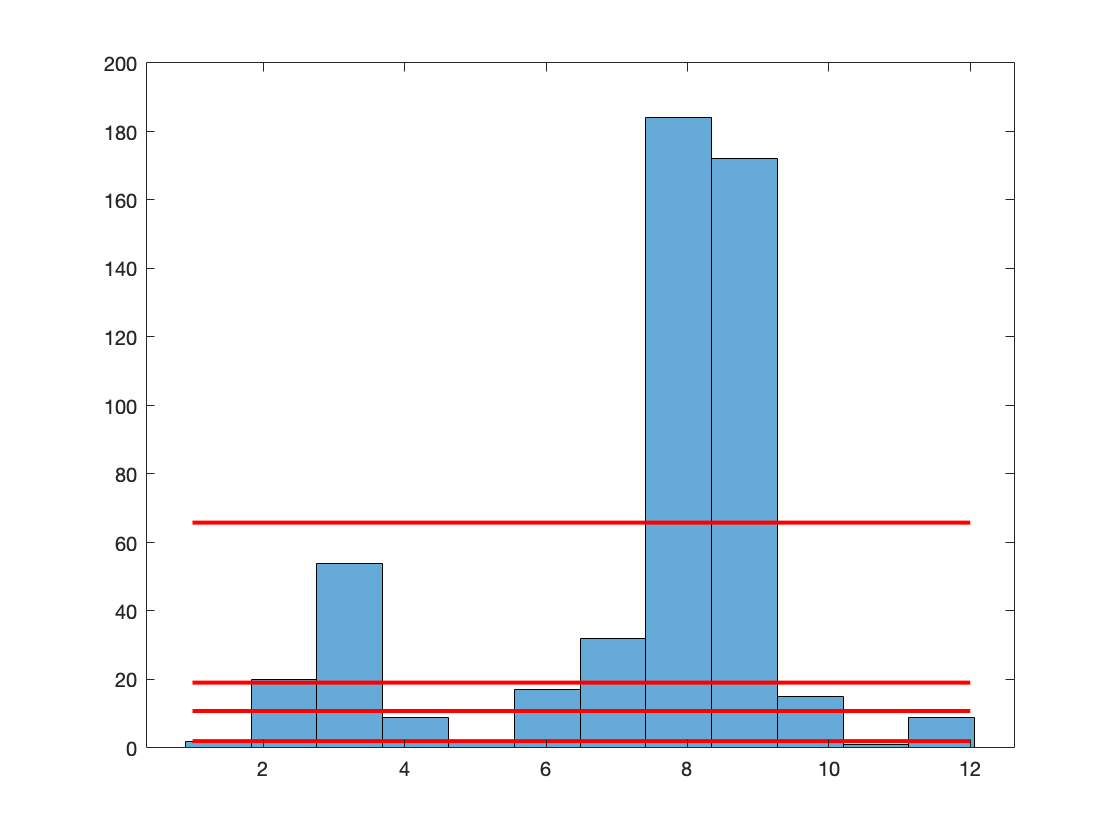

data = readcell([pwd, '/datasets/forestfires.csv']);
months = data(2:length(data),3);
c = containers.Map;
c('jan') = 1; c('feb')= 2; c('mar')= 3; c('apr')= 4; c('may')= 5; c('jun')= 6; c('jul')= 7; c('aug')= 8; c('sep')= 9; c('oct')= 10; c('nov')= 11; c('dec')= 12;
keys(c);
month_nums = NaN*zeros(length(months),1);
for k = 1:length(months)
    month_nums(k) = c(months{k});
end
Z=histcounts(month_nums,12);
Y = quantile(Z,4);
close all;
histogram(month_nums,12)
hold on
for k=1:length(Y)
plot(Y(k)*ones(12,1),'r',"LineWidth",2)
end
hold off

Based on that we change the correspondence between months and corresponding number

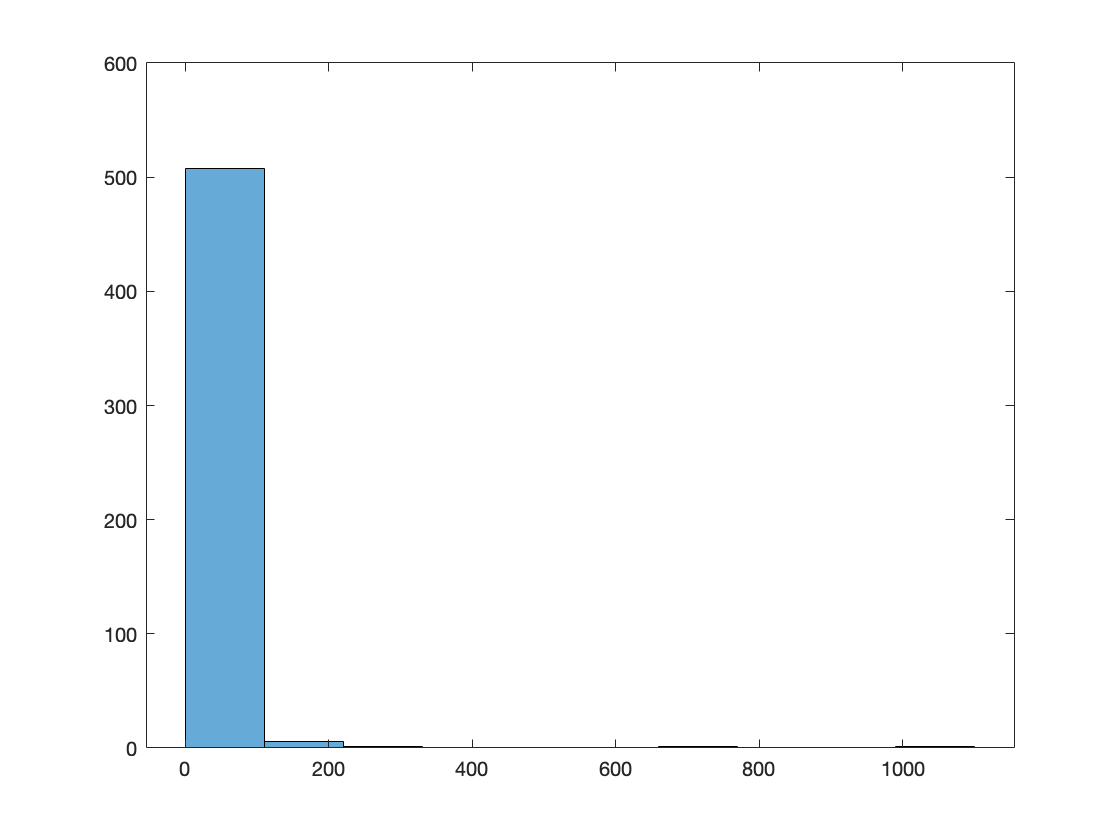

c = containers.Map;
c('jan') = -2; c('feb')= 0; c('mar')= 1; c('apr')= -1; c('may')= -2; c('jun')= 0; c('jul')= 1; c('aug')= 2; c('sep')= 2; c('oct')= 0; c('nov')= -2; c('dec')= -1;
keys(c);
month_nums = NaN*zeros(length(months),1);
for k = 1:length(months)
    month_nums(k) = c(months{k});
end
U = NaN * ones(11, length(data) - 1);
U(1,:) = cell2mat(data(2:length(data),1))';
U(2,:) = cell2mat(data(2:length(data),2))';
U(3,:) = month_nums';
U(4,:) = cell2mat(data(2:length(data),5))';
U(5,:) = cell2mat(data(2:length(data),6))';
U(6,:) = cell2mat(data(2:length(data),7))';
U(7,:) = cell2mat(data(2:length(data),8))';
U(8,:) = cell2mat(data(2:length(data),9))';
U(9,:) = cell2mat(data(2:length(data),10))';
U(10,:) = cell2mat(data(2:length(data),11))';
U(11,:) = cell2mat(data(2:length(data),12))';
Y = cell2mat(data(2:length(data),13))';
histogram(Y,10)

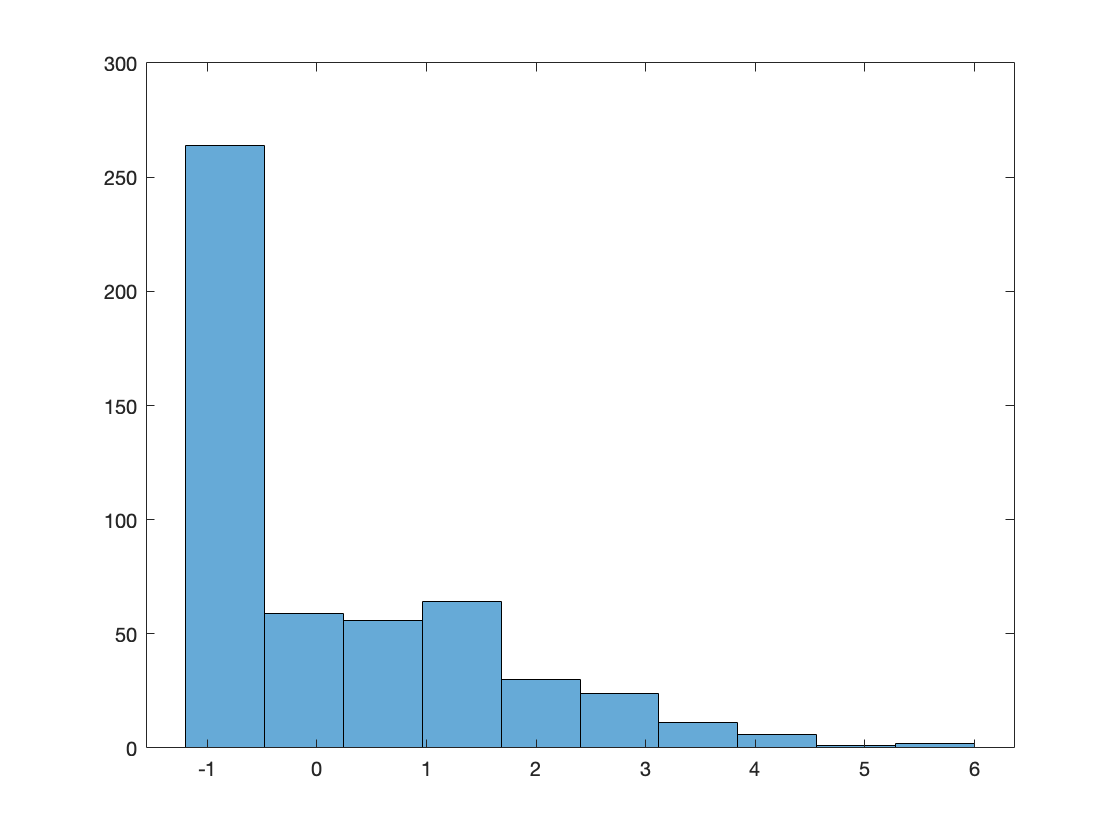

% process data
Y = log(Y+1)-1;
histogram(Y,10)

for feats = 1:11
 U(feats,:)=(U(feats,:)-mean(U(feats,:)))/std(U(feats,:));
end